Companion software for "Volker Ziemann, *Hands-on Accelerator physics using MATLAB, CRCPress, 2019*" (https://www.crcpress.com/9781138589940)

# Free-electron laser oscillator (Section 10.4)

Volker Ziemann, 211114, CC-BY-SA-4.0

**Important:** requires the elliptic package from [https://github.com/moiseevigor/elliptic](https://github.com/moiseevigor/elliptic) located in a subdirectory below the present one (for the fast evaluation of elliptic functions).

Like the example for the SASE FEL `SaseFreeElectronLaser.mlx` is this simulation based on numericall integrating Equation 10.32. The main difference is that here we operate at low current jcurr and assume that the laser field is recirculated by mirrors and meet a fresh electron bunch on the next iteration.

First we define the `mirror_losses` to be 0.01, the initial complex field `a` of the laser and the scaled current `jcurr`, which represents the peak current of the electron distribution. Moreover, we define the initial distribution of electrons in the ponderomotive field and the number N of electrons used in the simulation. From Equation 10.32 we see that the magnnitude of a, which is a0 describes the oscillation frequency $\Omega_s$ in the ponderomotive field.

clear all; close all; tic
addpath ./elliptic               % needed for elliptic12
mirror_losses=0.01;              % 0.01=1% extracted
a0=1e-8; phi=0; a=a0*exp(i*phi); % initial amplitude and phase of laser
jcurr=1;                         % scaled current from Equation 10.32
x0=[pi/2,2.6]; dx=[2*pi,0.1];    % center and spread of distribution
N=1000;                          % number of particles
Omegas=sqrt(a0);                 % synchrotron frequency

Next we need to define some parameters needed for annotating the plots. Since the increase of the field during one pass through the undulator does not grows significantly we decide to split the simulation within on pass through the unduator into `nstep=5` steps, rather than 100, as in the SASE suimulation. `Nrep`, on th other hand, specifies the number of round-trips of the laser caused by the mirrors. On each of these trips the laser interacts with  a fresh electron bunch that is provided by an accelerator. 

axis_scale=[-pi/2,3*pi/2,-17,17];
ypos=0.95*axis_scale(3)+0.05*axis_scale(4); % where to place text
zeta=-pi/2:0.01:3*pi/2; 
nstep=5; dt=1/nstep; tau=(1:nstep)/nstep;   % steps along the undulator
Nrep=100;                                   % iterations = round-trips of the laser 

Now we start iterating and first generate a fresh electron distribution that we display as a cloud of green dots.

data=zeros(Nrep,4);
for rep=1:Nrep     % iteration over round-trips
  hold off
  a00=abs(a);      % needed to caluclate the gain in this iteration
  x1(:,1)=x0(1)+(rand(N,1)-0.5)*dx(1); % initial distribution
  x1(:,2)=x0(2)+(rand(N,1)-0.5)*dx(2); 
  plot(x1(:,1),x1(:,2),'g.')
  if (rep==1) dx0=dx(2); rms0=std(x1(:,2)); end

In the following loop over nstep iterations we follow the electron distribution as it passes through the undulator. In each step we update the electron coordinates and calculate the bunching factor `bf` that we subsequently use to update the field `a `before plotting the new electron coordinates as red dots. 

  hold on; % draw new image 
  for m=1:nstep      % one pass through the undulator
    Omegas=sqrt(abs(a)); phi=phase(a);   % needed for electron dynamics
    parfor k=1:N                         % update electron phase space
      x1(k,:)=pendulumtracker2_phase(x1(k,:),Omegas,phi,dt);
    end
    bf=sum(exp(-i*x1(:,1)))/size(x1,1);  % bunching factor <exp(-i*zeta)>
    a=a-jcurr*bf*dt;                     % update laser field, Eq. 10.32   
  end
  plot(x1(:,1),x1(:,2),'r.'); rms1=std(x1(:,2)); 

Now we reduce the field as a consequence of the mirror losses, plot separatrix and annotate the plot.

  a=a*(1-mirror_losses);
  title(['Iteration   ',num2str(rep),' of ',num2str(Nrep)])
  separatrix=2*Omegas*cos(0.5*(zeta-pi/2+phi));
  plot(zeta,separatrix,'k',zeta,-separatrix,'k'); 
  set(gca,'xtick',[-pi/2,0,pi/2,pi,3*pi/2],'fontsize',14, ...
      'xticklabels',{'-\pi/2','0','\pi/2','\pi','3\pi/2'}) 
  axis(axis_scale); xlabel('\zeta'); ylabel('\nu') 
  text(-pi/4,ypos,['abs(a) = ',num2str(abs(a),3),' '],'fontsize',16) 

Before the next iteration, we save a number of interesting parameters for later plots to the array `data`.

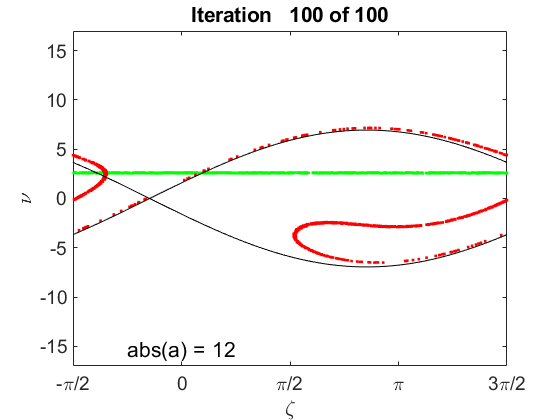

Elapsed time is 43.871730 seconds.


  data(rep,1)=abs(a);
  data(rep,2)=phase(a)*180/pi;
  data(rep,3)=(abs(a)-a00)/a00;
  data(rep,4)=rms1/rms0; 
  pause(0.001);
  if (mod(rep,100)==0) toc; end
end

Once the simulation is complete, we plot the `data`. the first plot shows the evolution of the magnitude of the field and the second plot shows its phase, whereas the third plot shows the gain per single pass through the undulator. Finally the last plot shows the increase in momentum spread of the electrons.   

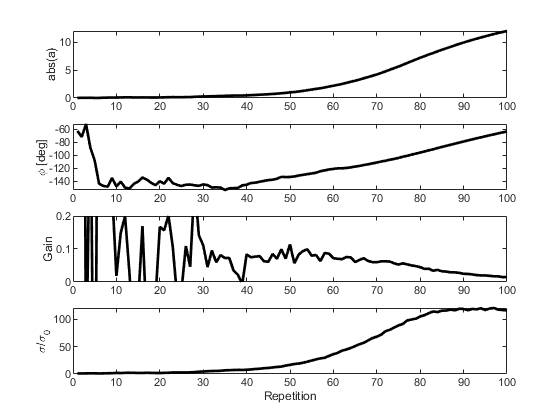

figure
rep=1:Nrep;
subplot(4,1,1); plot(rep,data(:,1),'k','LineWidth',2); ylabel('abs(a)');
subplot(4,1,2); plot(rep,data(:,2),'k','LineWidth',2); ylabel('\phi [deg]');
subplot(4,1,3); plot(rep,data(:,3),'k','LineWidth',2); ylabel('Gain');
ylim([0,0.2]);
subplot(4,1,4); plot(rep,data(:,4),'k','LineWidth',2); ylabel('\sigma/\sigma_0');
xlabel('Repetition');

Now feel free to play with the parameters to your heart's content!

## Appendix

The function `pendulumtracker2_phase()` integrates the equations of motion for a mathematical pendulum in terms of Jacobi elliptic functions. It is very similar to the one used in Chapter 5 (see those examples), exept this one takes the phase of the ponderomotive force $\phi$ into account.

function xout=pendulumtracker2_phase(x,omega,phi,dt)
x(1)=x(1)-pi/2+phi;   % adjust to new phase
k2=(0.5*x(2)/omega)^2+sin(0.5*x(1))^2; k=sqrt(k2);
if (x(1)>pi) x(1)=x(1)-2*pi; end
if (x(1)<-pi) x(1)=x(1)+2*pi; end
s=1; if (x(1)<0) s=-s; x(1)=-x(1); end
s1=1; if (x(2)<0) s1=-s1; end
if (k>1)   % outside separatrix; check this part next
  % disp('outside')
  kelf=ellipke(1/k2);
  trev=2*kelf/(k*omega);
  t0=mod(dt,trev);
  tmp=s1*k*omega*t0+s*elliptic12(0.5*x(1),1/k2);
  [sn,cn,dn]=ellipj(tmp,1/k2);    
  if (abs(tmp) > kelf) sn=-sn; end
  xout(1)=2*asin(sn);
  xout(2)=2*s1*omega*k*dn;
else       % inside separatrix
  %disp('inside')
  trev=4*ellipke(k2)/omega;
  t0=mod(dt,trev);
  z0=asin(min(1,sin(0.5*x(1))/k));
  tmp=s1*omega*t0+s*elliptic12(z0,k2);
  [sn,cn,dn]=ellipj(tmp,k2);  
  xout(1)=2*asin(k*sn);
  xout(2)=2*s1*omega*k*cn;
end
x(1)=x(1)+pi/2-phi;    % adjust phase back
xout(1)=xout(1)+pi/2-phi;
if (xout(1)>3*pi/2) xout(1)=xout(1)-2*pi; end  % cast in range
if (xout(1)<-pi/2) xout(1)=xout(1)+2*pi; end
end